clear

## specify data folder

dataFolder = '~/drive/Recon4IMD/WP2_MetNetwork/T2.3_Metabolic_biomarkers/results/crossMapping'; dataFolder = 'F:\.shortcut-targets-by-id\1Iz0jcL2iznigEVRO8dO1E_t7T4Ra7qFy\Recon4IMD\WP2_MetNetwork\T2.3_Metabolic_biomarkers\results\crossMapping'; dataFolder = '~/Projects/crossMapping';

dataFolder = fileparts(fileparts(pwd));
%

## Load ICIMD Gene OMIM number

icimdGeneMim = readtable([dataFolder filesep 'ICIMD' filesep 'ICIMD_VMH_OMIM.xlsx'], 'Range', 'L2:L1453', 'ReadVariableNames', false);
icimdGeneMim = unique(icimdGeneMim);
icimdGeneMim = rmmissing(icimdGeneMim);
icimdGeneMim = table2array(icimdGeneMim);

% Load ICIMD Gene Symbols
icimdGeneSym = readtable([dataFolder filesep 'ICIMD' filesep 'ICIMD_VMH_OMIM.xlsx'], 'Range', 'K2:K1453', 'ReadVariableNames', false);
icimdGeneSym = unique(icimdGeneSym);
icimdGeneSym = rmmissing(icimdGeneSym);
icimdGeneSym = table2cell(icimdGeneSym);

## Load MetabERN Gene OMIM number

metabErnGeneMim = readtable([dataFolder, filesep 'MetabERN' filesep 'METABERN_Patients_Def_cmb2_rf1.xlsx'], 'Range', 'G3:G1154', 'ReadVariableNames', false);
metabErnGeneMim = rmmissing(metabErnGeneMim);
metabErnGeneMim = unique(metabErnGeneMim);
metabErnGeneMim = table2array(metabErnGeneMim);

## Load ReconX gene symbols

reconxGeneSym = readtable([dataFolder filesep 'ReconX' filesep 'GeneNameMapping.xlsx'], 'Range', 'B2:B3324', 'ReadVariableNames', false);
reconxGeneSym = unique(reconxGeneSym);
reconxGeneSym = rmmissing(reconxGeneSym);
reconxGeneSym = table2cell(reconxGeneSym);

## Get gene symbols from MIM Ids to convert: Gene Symbols -> Gene MIM Ids

mimData = readtable([dataFolder, filesep 'OMIM' filesep 'genemap2_RF.xlsx']);
mimId = table2array(mimData(:,6));
mimSymbol = table2cell(mimData(:,7));

## Convert ReconX gene Symbols into Gene OMIM IDs

matchGeneSym = ismember(mimSymbol, reconxGeneSym);
reconxGeneMim = mimId(matchGeneSym);

## Convert MetabERN MIM IDs to gene symbols

matchGeneMIM = ismember(mimId, metabErnGeneMim);
metabErnGeneSym = mimSymbol(matchGeneMIM);
metabErnGeneSym = unique(metabErnGeneSym);

## Create the proportional Venn diagram using gene MIM number as namespace

% icimd = A, reconX = B, metabERN = C,
icimdGeneMim = unique(icimdGeneMim);
reconxGeneMim = unique(reconxGeneMim);
metabErnGeneMim = unique(metabErnGeneMim);

% B&C A&B&C (B&C-A&B&C)
reconxMetabErn = intersect(reconxGeneMim, metabErnGeneMim);
reconxMetabErnIcimd = intersect(reconxMetabErn, icimdGeneMim);
reconxMetabErn = setdiff(reconxMetabErn, reconxMetabErnIcimd);

% (A&B-A&B&C)
icimdReconx = intersect(icimdGeneMim, reconxGeneMim);
icimdReconx = setdiff(icimdReconx, reconxMetabErnIcimd);

% (A&C - A&B&C)
icimdMetabErn = intersect(icimdGeneMim, metabErnGeneMim);
icimdMetabErn = setdiff(icimdMetabErn, reconxMetabErnIcimd);

% A = A-A&B-A&C-A&B&C
icimdNo = setdiff(icimdGeneMim, icimdReconx);
icimdNo = setdiff(icimdNo, icimdMetabErn);
icimdNo = setdiff(icimdNo, reconxMetabErnIcimd);
icimdNo = numel(icimdNo);

% B = B-A&B-B&C-A&B&C
reconxNo = setdiff(reconxGeneMim, icimdReconx);
reconxNo = setdiff(reconxNo, reconxMetabErn);
reconxNo = setdiff(reconxNo, reconxMetabErnIcimd);
reconxNo = numel(reconxNo);

% C = C-C&B-C&A-A&B&C
metabErnNo = setdiff(metabErnGeneMim, icimdMetabErn);
metabErnNo = setdiff(metabErnNo, reconxMetabErn);
metabErnNo = setdiff(metabErnNo, reconxMetabErnIcimd);
metabErnNo = numel(metabErnNo);

% Get the number of each part
icimdReconxNum = numel(icimdReconx);
icimdMetabErnNum = numel(icimdMetabErn);
reconxMetabErnNum = numel(reconxMetabErn);
reconxMetabErnIcimdNum = numel(reconxMetabErnIcimd);

save('reconxMetabErnIcimd', 'reconxMetabErnIcimd');

% The Inout format would be: [A AB B BC C AC ABC]
vennInput = [icimdNo, icimdReconxNum, reconxNo, reconxMetabErnNum, metabErnNo, icimdMetabErnNum, reconxMetabErnIcimdNum];
error = 0.1;
vennX(vennInput, error )

ans =     5.0100   -3.5800  294.5000   -2.3500    3.7100   -3.2500    1.9400


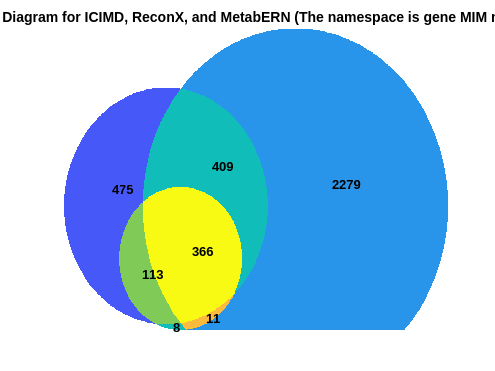

title('Venn Diagram for ICIMD, ReconX, and MetabERN (The namespace is gene MIM number)')

## Create the proportional Venn diagram using gene Symbols as namespace

% icimd = A, reconX = B, metabERN = C,
icimdGeneSym = unique(icimdGeneSym);
reconxGeneSym = unique(reconxGeneSym);
metabErnGeneSym = unique(metabErnGeneSym);

% B&C A&B&C (B&C-A&B&C)
reconxMetabErn = intersect(reconxGeneSym, metabErnGeneSym);
reconxMetabErnIcimd = intersect(reconxMetabErn, icimdGeneSym);
reconxMetabErn = setdiff(reconxMetabErn, reconxMetabErnIcimd);

% (A&B-A&B&C)
icimdReconx = intersect(icimdGeneSym, reconxGeneSym);
icimdReconx = setdiff(icimdReconx, reconxMetabErnIcimd);

% (A&C - A&B&C)
icimdMetabErn = intersect(icimdGeneSym, metabErnGeneSym);
icimdMetabErn = setdiff(icimdMetabErn, reconxMetabErnIcimd);

% A = A-A&B-A&C-A&B&C
icimdNo = setdiff(icimdGeneSym, icimdReconx);
icimdNo = setdiff(icimdNo, icimdMetabErn);
icimdNo = setdiff(icimdNo, reconxMetabErnIcimd);
icimdNo = numel(icimdNo);

% B = B-A&B-B&C-A&B&C
reconxNo = setdiff(reconxGeneSym, icimdReconx);
reconxNo = setdiff(reconxNo, reconxMetabErn);
reconxNo = setdiff(reconxNo, reconxMetabErnIcimd);
reconxNo = numel(reconxNo);

% C = C-C&B-C&A-A&B&C
metabErnNo = setdiff(metabErnGeneSym, icimdMetabErn);
metabErnNo = setdiff(metabErnNo, reconxMetabErn);
metabErnNo = setdiff(metabErnNo, reconxMetabErnIcimd);
metabErnNo = numel(metabErnNo);

% Get the number of each part
icimdReconxNum = numel(icimdReconx);
icimdMetabErnNum = numel(icimdMetabErn);
reconxMetabErnNum = numel(reconxMetabErn);
reconxMetabErnIcimdNum = numel(reconxMetabErnIcimd);

save('reconxMetabErnIcimd', 'reconxMetabErnIcimd');

% The Inout format would be: [A AB B BC C AC ABC]
vennInput = [icimdNo, icimdReconxNum, reconxNo, reconxMetabErnNum, metabErnNo, icimdMetabErnNum, reconxMetabErnIcimdNum];
error = 0.1;
vennX(vennInput, error )

ans =    12.0800  -10.2200  347.0300   -6.8900    8.4900   -7.7000    6.1000


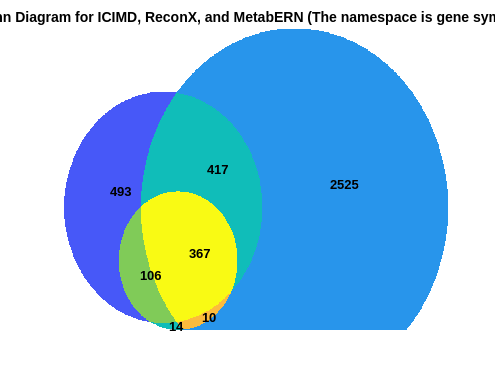

title('Venn Diagram for ICIMD, ReconX, and MetabERN (The namespace is gene symbols)')

## Load U-IMD Gene OMIM number

uimdData = readtable([dataFolder, filesep', 'UIMD', filesep, 'UIMD_metabolites_update_fz.xlsx'], 'Sheet', 'Tabelle1', 'ReadRowNames',false);

uimdDisease = table2cell(uimdData(:, 3));
uimdMetHmdb = table2cell(uimdData(:, 5));
uimdGeneMim = table2array(uimdData(:, 8));

## Convert U-IMD MIM IDs to gene symbols

nlt = numel(uimdGeneMim);
uimdGeneSym = cell(nlt, 1);

for i = 1:numel(uimdGeneMim)
    id = find(ismember(mimId, uimdGeneMim(i)));
    if any(id)
        uimdGeneSym{i} = mimSymbol{id};
    else
        uimdGeneSym{i} = 'Nan';
    end
end

## Create the Gene Venn diagram for ICIMD, metabERN, ReconX, and U-IMD using Gene MIM numbers as namespaces

ICIMD = A

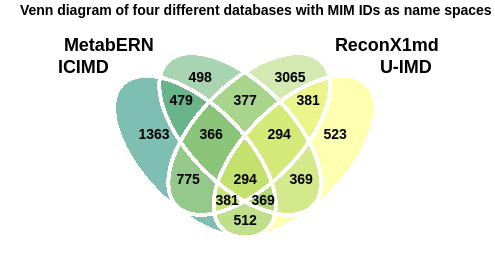

An = numel(unique(icimdGeneMim));

% MetabERN = B
Bn = numel(unique(metabErnGeneMim));

% ReconX = C
Cn = numel(unique(reconxGeneMim));

% U-IMD = D
Dn = numel(unique(uimdGeneMim));

% A&B
AB = intersect(icimdGeneMim, metabErnGeneMim);
ABn = numel(AB);

% A&C
AC = intersect(icimdGeneMim, reconxGeneMim);
ACn = numel(AC);

% A&D
AD = intersect(icimdGeneMim, uimdGeneMim);
ADn = numel(AD);

% B&C
BC = intersect(metabErnGeneMim, reconxGeneMim);
BCn = numel(BC);

% B&D
BD = intersect(metabErnGeneMim, uimdGeneMim);
BDn = numel(BD);

% C&D
CD = intersect(reconxGeneMim, uimdGeneMim);
CDn = numel(CD);

% A&B&C
ABC = intersect(AB, reconxGeneMim);
ABCn = numel(ABC);

% A&B&D
ABD = intersect(AB, uimdGeneMim);
ABDn = numel(ABD);

% A&C&D
ACD = intersect(AC, uimdGeneMim);
ACDn = numel(ACD);

% B&C&D
BCD = intersect(BC, uimdGeneMim);
BCDn = numel(BCD);

% A&B&C&D.
ABCD = intersect(ABC, uimdGeneMim);
ABCDn = numel(ABCD);

mysets = ["ICIMD" "MetabERN" "ReconX1md" "U-IMD"];
mylabels = [An, Bn, Cn, Dn, ABn, ACn, ADn, BCn, BDn, CDn, ABCn, ABDn, ACDn, BCDn, ABCDn];
c = summer(4);
venn(4,'sets',mysets,'labels',mylabels,'colors',c,'alpha',0.5,'edgeC',[1 1 1],'edgeW',3);
title('Venn diagram of four different databases with MIM IDs as name spaces')

## Claculate intersection coverage

fprintf('%s%d\n', 'Gene intersection (using MIM IDs as namespace) is:  ', ABCDn);

Gene intersection (using MIM IDs as namespace) is:  294


% Find intersect IMD disease
id = ismember(uimdGeneMim, ABCD);
intersectDisease = uimdDisease(id);
fprintf('%s%d%s%d%s\n', 'The Number of IM Disease it covers: ', numel(unique(intersectDisease)), ' of the total ', numel(unique(uimdDisease)), ' IMDs');

The Number of IM Disease it covers: 313 of the total 545 IMDs


## Mapping Gene intersect to Metabolite intersect using U-IMD as a dataset for mapping

intersectMet = uimdMetHmdb(id);
intersectMet = unique(strtrim(intersectMet));
fprintf('%s%d\n', 'Number of IMD metabolite biomarker mapping from U-IMD (usin Gene MIM as namespaces): ', numel(intersectMet));

Number of IMD metabolite biomarker mapping from U-IMD (usin Gene MIM as namespaces): 299


## Create the Gene Venn diagram for ICIMD, metabERN, ReconX, and U-IMD using Gene Symbols as namespaces

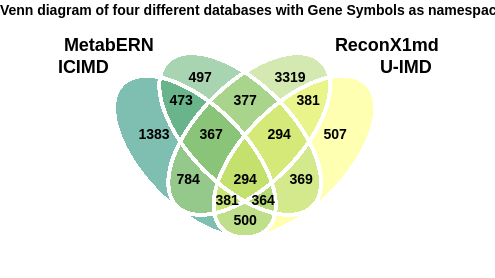

% ICIMD = A
An = numel(unique(icimdGeneSym));

% MetabERN = B
Bn = numel(unique(metabErnGeneSym));

% ReconX = C
Cn = numel(unique(reconxGeneSym));

% U-IMD = D
Dn = numel(unique(uimdGeneSym));

% A&B
AB = intersect(icimdGeneSym, metabErnGeneSym);
ABn = numel(AB);

% A&C
AC = intersect(icimdGeneSym, reconxGeneSym);
ACn = numel(AC);

% A&D
AD = intersect(icimdGeneSym, uimdGeneSym);
ADn = numel(AD);

% B&C
BC = intersect(metabErnGeneSym, reconxGeneSym);
BCn = numel(BC);

% B&D
BD = intersect(metabErnGeneSym, uimdGeneSym);
BDn = numel(BD);

% C&D
CD = intersect(reconxGeneSym, uimdGeneSym);
CDn = numel(CD);

% A&B&C
ABC = intersect(AB, reconxGeneSym);
ABCn = numel(ABC);

% A&B&D
ABD = intersect(AB, uimdGeneSym);
ABDn = numel(ABD);

% A&C&D
ACD = intersect(AC, uimdGeneSym);
ACDn = numel(ACD);

% B&C&D
BCD = intersect(BC, uimdGeneSym);
BCDn = numel(BCD);

% A&B&C&D.
ABCD = intersect(ABC, uimdGeneSym);
ABCDn = numel(ABCD);

mysets = ["ICIMD" "MetabERN" "ReconX1md" "U-IMD"];
mylabels = [An, Bn, Cn, Dn, ABn, ACn, ADn, BCn, BDn, CDn, ABCn, ABDn, ACDn, BCDn, ABCDn];
c = summer(4);
venn(4,'sets',mysets,'labels',mylabels,'colors',c,'alpha',0.5,'edgeC',[1 1 1],'edgeW',3);
title('Venn diagram of four different databases with Gene Symbols as namespaces')

## Claculate intersection coverage

fprintf('%s%d\n', 'Gene intersection (using Gene Symbols as namespace) is:  ', ABCDn);

Gene intersection (using Gene Symbols as namespace) is:  294


% Find intersect IMD disease
id = ismember(uimdGeneSym, ABCD);
intersectDisease = uimdDisease(id);
fprintf('%s%d%s%d%s\n', 'The Number of IM Disease it covers: ', numel(unique(intersectDisease)), ' of the total ', numel(unique(uimdDisease)), ' IMDs');

The Number of IM Disease it covers: 313 of the total 545 IMDs


## Mapping Gene intersect to Metabolite intersect using U-IMD as a dataset for mapping

intersectMet = uimdMetHmdb(id);
fprintf('%s%d\n', 'Number of IMD metabolite biomarker mapping from U-IMD (usin Gene Symbols as Gene namespaces): ', numel(unique(strtrim(intersectMet))));

Number of IMD metabolite biomarker mapping from U-IMD (usin Gene Symbols as Gene namespaces): 299


## Trimming HMDB vector of common metabolites

% one of the metabolite names has a ";" sign in it, lets delete that !
intersectMet = cellfun(@(x) strrep(x, ';', ''), intersectMet, 'UniformOutput', false);

## Making a result table

biomarkerTable = cell2table(uimdGeneSym(id));
biomarkerTable(:,2) = cell2table(intersectMet);
biomarkerTable = unique(biomarkerTable, 'rows');
newVariableNames = {'BiomarkerGenes', 'IMDMetBiomarkers'};
biomarkerTable = renamevars(biomarkerTable, {'Var1','Var2'}, newVariableNames);

## Get IMD biomarker metabolites info from MetaNetX website

commonMets = table2cell(biomarkerTable(:,2));

% Select to recalculate the results or load it from previous calculations
bioMetLoadData = false;

if ~bioMetLoadData

    nlt = numel(commonMets);

    bioMetNames = cell(nlt,1);
    bioMetMetanetx = cell(nlt, 1);
    bioMetChebi = cell(nlt, 1);
    bioMetHmdb = cell(nlt, 1);
    bioMetSwisslipids = cell(nlt, 1);
    bioMetVmh = cell(nlt, 1);

    for i = 1:nlt
        success = false;
        met = commonMets{i};

        while ~success
            try
                fprintf('%s%d%s%d\n', 'Biomarker Metabolite ', i, 'th of ', nlt);
                metInfo = metanetxMapper(string(met));

                bioMetNames(i) = cellstr(metInfo.name);
                bioMetMetanetx(i) = cellstr(metInfo.metanetx);
                bioMetChebi(i) = cellstr(metInfo.chebi);
                bioMetHmdb(i) = cellstr(metInfo.hmdb);
                bioMetSwisslipids(i) = cellstr(metInfo.swisslipids);
                bioMetVmh(i) = cellstr(metInfo.vmh);
                success = true;
            catch exception
                fprintf('%s%d\n', 'paused for i = ', i);
                pause(1.5)
            end
        end
    end

    % Extend the result table
    biomarkerTable(:, 3) = cell2table(bioMetNames);
    biomarkerTable(:, 4) = cell2table(bioMetMetanetx);
    biomarkerTable(:, 5) = cell2table(bioMetChebi);
    biomarkerTable(:, 6) = cell2table(bioMetHmdb);
    biomarkerTable(:, 7) = cell2table(bioMetSwisslipids);
    biomarkerTable(:, 8) = cell2table(bioMetVmh);

    newVariableNames = {'MetNames', 'MetaNetXID', 'CHEBI', 'HMDB', 'SwissLipids', 'VMH'};
    biomarkerTable = renamevars(biomarkerTable, {'Var3', 'Var4', 'Var5', 'Var6', 'Var7', 'Var8'}, newVariableNames);

    % Write this table to an excel file
    % Set the saving path and file name
    geneBiomarkerTable = biomarkerTable ;
    path = [dataFolder, filesep, 'Results', filesep, 'Gene Biomarkers.xlsx'];
    % Remove the old file if exists
    if exist(path, 'file')
        delete(path);
    end
    writetable(geneBiomarkerTable, path);

    % Make an excel file only for IMD metabolite biomarkers
    % Make table for IMD biomarkers (unique HMDB IDs)
    nonEmptyID = ~ismissing(biomarkerTable(:,2));
    biomarkerTable = biomarkerTable(nonEmptyID, :);
    [~, uniqueID] = unique(biomarkerTable(:,2));
    biomarkerTable = biomarkerTable(uniqueID, :);

    % Find the IMD protein biomarkers and exclude them from the list
    proteinID = contains(table2cell(biomarkerTable(:, 2)), 'HMDBP');
    fprintf('%s\n%d%s%d%s\n', 'Number of IMD protein biomarkers is ', sum(proteinID), ' Out of total ', numel(biomarkerTable(:, 2)), ' biomarkers')

    % exclude proteins from the list
    biomarkerTable = biomarkerTable(~proteinID, :);

    % exclude IMD Gene biomarker from the list
    biomarkerTable = biomarkerTable(:, 2:end);

    % Save this table to an excel file
    path = [dataFolder, filesep, 'Results', filesep, 'Metabolite Biomarkers.xlsx'];

    % Remove the old file if exists
    if exist(path, 'file')
        delete(path);
    end
    writetable(biomarkerTable, path);
end

Biomarker Metabolite 1th of 1294
Biomarker Metabolite 2th of 1294
Biomarker Metabolite 3th of 1294
Biomarker Metabolite 4th of 1294
Biomarker Metabolite 5th of 1294
Biomarker Metabolite 6th of 1294
Biomarker Metabolite 7th of 1294
Biomarker Metabolite 8th of 1294
Biomarker Metabolite 9th of 1294
Biomarker Metabolite 10th of 1294
Biomarker Metabolite 11th of 1294
Biomarker Metabolite 12th of 1294
Biomarker Metabolite 13th of 1294
Biomarker Metabolite 14th of 1294
Biomarker Metabolite 15th of 1294
Biomarker Metabolite 16th of 1294
Biomarker Metabolite 17th of 1294
Biomarker Metabolite 18th of 1294
Biomarker Metabolite 19th of 1294
Biomarker Metabolite 20th of 1294
Biomarker Metabolite 21th of 1294
Biomarker Metabolite 22th of 1294
Biomarker Metabolite 23th of 1294
Biomarker Metabolite 24th of 1294
Biomarker Metabolite 25th of 1294
Biomarker Metabolite 26th of 1294
Biomarker Metabolite 27th of 1294
Biomarker Metabolite 28th of 1294
Biomarker Metabolite 29th of 1294
Biomarker Metabolite 30

paused for i = 329


Biomarker Metabolite 329th of 1294
Biomarker Metabolite 330th of 1294
Biomarker Metabolite 331th of 1294
Biomarker Metabolite 332th of 1294
Biomarker Metabolite 333th of 1294
Biomarker Metabolite 334th of 1294
Biomarker Metabolite 335th of 1294
Biomarker Metabolite 336th of 1294
Biomarker Metabolite 337th of 1294
Biomarker Metabolite 338th of 1294
Biomarker Metabolite 339th of 1294
Biomarker Metabolite 340th of 1294
Biomarker Metabolite 341th of 1294
Biomarker Metabolite 342th of 1294
Biomarker Metabolite 343th of 1294
Biomarker Metabolite 344th of 1294
Biomarker Metabolite 345th of 1294
Biomarker Metabolite 346th of 1294
Biomarker Metabolite 347th of 1294
Biomarker Metabolite 348th of 1294
Biomarker Metabolite 349th of 1294
Biomarker Metabolite 350th of 1294
Biomarker Metabolite 351th of 1294
Biomarker Metabolite 352th of 1294
Biomarker Metabolite 353th of 1294
Biomarker Metabolite 354th of 1294
Biomarker Metabolite 355th of 1294
Biomarker Metabolite 356th of 1294
Biomarker Metabolite

Number of IMD protein biomarkers is 
27 Out of total 297 biomarkers


% In the case of loading previous calculations
if bioMetLoadData
    biomarkerTable = readtable([dataFolder filesep 'Results' filesep 'Metabolite Biomarkers.xlsx'], 'ReadVariableNames', false, 'ReadRowNames',false);
    bioMetNames = table2cell(biomarkerTable(:, 2));
    bioMetMetanetx = table2cell(biomarkerTable(:, 3));
    bioMetChebi = table2cell(biomarkerTable(:, 4));
    bioMetHmdb = table2cell(biomarkerTable(:, 5));
    bioMetSwisslipids = table2cell(biomarkerTable(:, 6));
    bioMetVmh = table2cell(biomarkerTable(:, 7));
end

## Convert ReconX vmh metabolite list to other metabolite IDs

% Select to recalculate the results or load it from previous calculations
reconxLoadData = 0;

if ~reconxLoadData
    % Load ReconX Metabolite Names
    % Note that ReconX metabolite IDs are initially in VMH namespace
    reconxMets = readtable([dataFolder filesep 'ReconX' filesep 'met_strc_rBioNet_new_18_10_22_Table.xlsx'], 'Range', 'E2:E7922', 'ReadVariableNames', false, 'ReadRowNames',false);
    reconxMets = strtrim(table2array(reconxMets));

    nlt = numel(reconxMets);
    % use metanetxMapper
    reconxMetNames = cell(nlt,1);
    reconxMetMetanetx = cell(nlt, 1);
    reconxMetChebi = cell(nlt, 1);
    reconxMetHmdb = cell(nlt, 1);
    reconxMetSwisslipids = cell(nlt, 1);
    reconxMetVmh = cell(nlt, 1);

    for i = 1:nlt
        success = false;
        met = reconxMets{i};
        % Remove redundant quotation marks
        met = strrep(met, '''', '');
        % For more accurate response from MetaNetX website, vmhm is added at
        % the begginning of each VMH ID
        met = ['vmhM:', met];

        while ~success
            try
                fprintf('%s%d%s%d\n', 'ReconX Metabolite ', i, 'th of ', nlt);
                metInfo = metanetxMapper(string(met));
                reconxMetNames(i) = cellstr(metInfo.name);
                reconxMetMetanetx(i) = cellstr(metInfo.metanetx);
                reconxMetChebi(i) = cellstr(metInfo.chebi);
                reconxMetHmdb(i) = cellstr(metInfo.hmdb);
                reconxMetSwisslipids(i) = cellstr(metInfo.swisslipids);
                reconxMetVmh(i) = cellstr(metInfo.vmh);
                success = true;
            catch exception
                fprintf('%s%d\n', 'paused for i = ', i);
                pause(1.5)
            end
        end
    end

    % Extend the result table
    reconxMetsInfo = table(reconxMets, reconxMetNames, reconxMetMetanetx, ...
        reconxMetChebi, reconxMetHmdb, reconxMetSwisslipids, ...
        reconxMetVmh, 'VariableNames', {'reconxVmhNames', 'MetNames', 'MetaNetX',...
        'CHEBI', 'HMDB', 'SwissLipids', 'VMH'});

    % Save the table as an excel file in ReconX directory
    path = [dataFolder, filesep, 'ReconX', filesep, 'reconxMetabolites.xlsx'];
    if exist(path, 'file')
        delete(path);
    end
    writetable(reconxMetsInfo, path);
end

ReconX Metabolite 1th of 7921
ReconX Metabolite 2th of 7921
ReconX Metabolite 3th of 7921
ReconX Metabolite 4th of 7921
ReconX Metabolite 5th of 7921
ReconX Metabolite 6th of 7921
ReconX Metabolite 7th of 7921
ReconX Metabolite 8th of 7921
ReconX Metabolite 9th of 7921
ReconX Metabolite 10th of 7921
ReconX Metabolite 11th of 7921
ReconX Metabolite 12th of 7921
ReconX Metabolite 13th of 7921
ReconX Metabolite 14th of 7921
ReconX Metabolite 15th of 7921
ReconX Metabolite 16th of 7921
ReconX Metabolite 17th of 7921
ReconX Metabolite 18th of 7921
ReconX Metabolite 19th of 7921
ReconX Metabolite 20th of 7921
ReconX Metabolite 21th of 7921
ReconX Metabolite 22th of 7921
ReconX Metabolite 23th of 7921
ReconX Metabolite 24th of 7921
ReconX Metabolite 25th of 7921
ReconX Metabolite 26th of 7921
ReconX Metabolite 27th of 7921
ReconX Metabolite 28th of 7921
ReconX Metabolite 29th of 7921
ReconX Metabolite 30th of 7921
ReconX Metabolite 31th of 7921
ReconX Metabolite 32th of 7921
ReconX Metabolite

paused for i = 361


ReconX Metabolite 361th of 7921
ReconX Metabolite 362th of 7921
ReconX Metabolite 363th of 7921
ReconX Metabolite 364th of 7921
ReconX Metabolite 365th of 7921
ReconX Metabolite 366th of 7921
ReconX Metabolite 367th of 7921
ReconX Metabolite 368th of 7921
ReconX Metabolite 369th of 7921
ReconX Metabolite 370th of 7921
ReconX Metabolite 371th of 7921
ReconX Metabolite 372th of 7921
ReconX Metabolite 373th of 7921
ReconX Metabolite 374th of 7921
ReconX Metabolite 375th of 7921
ReconX Metabolite 376th of 7921
ReconX Metabolite 377th of 7921
ReconX Metabolite 378th of 7921
ReconX Metabolite 379th of 7921
ReconX Metabolite 380th of 7921
ReconX Metabolite 381th of 7921
ReconX Metabolite 382th of 7921
ReconX Metabolite 383th of 7921
ReconX Metabolite 384th of 7921
ReconX Metabolite 385th of 7921
ReconX Metabolite 386th of 7921
ReconX Metabolite 387th of 7921
ReconX Metabolite 388th of 7921
ReconX Metabolite 389th of 7921
ReconX Metabolite 390th of 7921
ReconX Metabolite 391th of 7921
ReconX M

paused for i = 832


ReconX Metabolite 832th of 7921
ReconX Metabolite 833th of 7921
ReconX Metabolite 834th of 7921
ReconX Metabolite 835th of 7921
ReconX Metabolite 836th of 7921
ReconX Metabolite 837th of 7921
ReconX Metabolite 838th of 7921
ReconX Metabolite 839th of 7921
ReconX Metabolite 840th of 7921
ReconX Metabolite 841th of 7921
ReconX Metabolite 842th of 7921
ReconX Metabolite 843th of 7921
ReconX Metabolite 844th of 7921
ReconX Metabolite 845th of 7921
ReconX Metabolite 846th of 7921
ReconX Metabolite 847th of 7921
ReconX Metabolite 848th of 7921
ReconX Metabolite 849th of 7921
ReconX Metabolite 850th of 7921
ReconX Metabolite 851th of 7921
ReconX Metabolite 852th of 7921
ReconX Metabolite 853th of 7921
ReconX Metabolite 854th of 7921
ReconX Metabolite 855th of 7921
ReconX Metabolite 856th of 7921
ReconX Metabolite 857th of 7921
ReconX Metabolite 858th of 7921
ReconX Metabolite 859th of 7921
ReconX Metabolite 860th of 7921
ReconX Metabolite 861th of 7921
ReconX Metabolite 862th of 7921
ReconX M

paused for i = 5016


ReconX Metabolite 5016th of 7921
ReconX Metabolite 5017th of 7921
ReconX Metabolite 5018th of 7921
ReconX Metabolite 5019th of 7921
ReconX Metabolite 5020th of 7921
ReconX Metabolite 5021th of 7921
ReconX Metabolite 5022th of 7921
ReconX Metabolite 5023th of 7921
ReconX Metabolite 5024th of 7921
ReconX Metabolite 5025th of 7921
ReconX Metabolite 5026th of 7921
ReconX Metabolite 5027th of 7921
ReconX Metabolite 5028th of 7921
ReconX Metabolite 5029th of 7921
ReconX Metabolite 5030th of 7921
ReconX Metabolite 5031th of 7921
ReconX Metabolite 5032th of 7921
ReconX Metabolite 5033th of 7921
ReconX Metabolite 5034th of 7921
ReconX Metabolite 5035th of 7921
ReconX Metabolite 5036th of 7921
ReconX Metabolite 5037th of 7921
ReconX Metabolite 5038th of 7921
ReconX Metabolite 5039th of 7921
ReconX Metabolite 5040th of 7921
ReconX Metabolite 5041th of 7921
ReconX Metabolite 5042th of 7921
ReconX Metabolite 5043th of 7921
ReconX Metabolite 5044th of 7921
ReconX Metabolite 5045th of 7921
ReconX Met

% In the case of loading previous calculations
if reconxLoadData
    reconxMetsInfo = readtable([dataFolder filesep 'ReconX' filesep 'reconxMetabolites.xlsx'], 'ReadVariableNames', false, 'ReadRowNames',false);
    reconxMets = table2cell(reconxMetsInfo(:,1));
    reconxMetNames = table2cell(reconxMetsInfo(:,2));
    reconxMetMetanetx = table2cell(reconxMetsInfo(:,3));
    reconxMetChebi = table2cell(reconxMetsInfo(:,4));
    reconxMetHmdb = table2cell(reconxMetsInfo(:,5));
    reconxMetSwisslipids = table2cell(reconxMetsInfo(:,6));
    reconxMetVmh = ctable2cell(reconxMetsInfo(:,7));
end

## Find the common metabolites between ReconX and IMD Metabolite Biomarkers

% Use MetaNetX as namespace
reconxMatchMetanetx = ismember(unique(bioMetMetanetx), unique(reconxMetMetanetx));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in ReconX is', '(MetaNetX ID as namespace): ', sum(reconxMatchMetanetx), '/', numel(unique(bioMetMetanetx)));

Number of IMD biomarker metabolites in ReconX is
(MetaNetX ID as namespace): 190/257



% Use Official common name as namespace
reconxMatchName = ismember(unique(bioMetNames), unique(reconxMetNames));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in ReconX is', '(Official Common Name as namespace):', sum(reconxMatchName), '/', numel(unique(bioMetNames)));

Number of IMD biomarker metabolites in ReconX is
(Official Common Name as namespace):192/257



% Use CHEBI as namespace
reconxMatchChebi = ismember(unique(bioMetChebi), unique(reconxMetChebi));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in ReconX is', '(CHEBI ID as namespace): ', sum(reconxMatchChebi), '/', numel(unique(bioMetChebi)));

Number of IMD biomarker metabolites in ReconX is
(CHEBI ID as namespace): 187/234



% Use VMH as namespace
reconxMatchVmh = ismember(unique(bioMetVmh), unique(reconxMetVmh));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in ReconX is', '(VMH ID as namespace): ', sum(reconxMatchVmh), '/', numel(unique(bioMetVmh)));

Number of IMD biomarker metabolites in ReconX is
(VMH ID as namespace): 190/190



% Use HMDB as namespace
reconxMatchHmdb = ismember(unique(bioMetHmdb), unique(reconxMetHmdb));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in ReconX is', '(HMDB ID as namespace): ', sum(reconxMatchHmdb), '/', numel(unique(bioMetHmdb)));

Number of IMD biomarker metabolites in ReconX is
(HMDB ID as namespace): 190/257



% Use SwissLipids as namespace
reconxMatchSwisslipids = ismember(unique(bioMetSwisslipids), unique(reconxMetSwisslipids));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in ReconX is', '(Swiss Lipids ID as namespace): ', sum(reconxMatchSwisslipids), '/', numel(unique(bioMetSwisslipids)));

Number of IMD biomarker metabolites in ReconX is
(Swiss Lipids ID as namespace): 22/26



% Use all the name spaces
reconxMatch = reconxMatchMetanetx + reconxMatchName + reconxMatchChebi + reconxMatchVmh + reconxMatchHmdb + reconxMatchSwisslipids;
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in ReconX is', '(Using all the namespaces): ', sum(logical(reconxMatch)), '/', numel(unique(bioMetHmdb)));


## Load and Convert Leiden Met IDs (SwissLipids and Chebi) into other databases IDs

% Select to recalculate the results or load it from previous calculations
leiLoadData = 0;

if ~leiLoadData
    % Leiden Metabolite list has either Swiss Lipids IDs, CHEBI IDs or they are empty or "NA" cells, some cells have two Swiss Lipid IDs splited by ";"
    leiData = readtable([dataFolder, filesep 'Leiden' filesep 'Complete_Targets_Dictionary_20220303.xlsx'], 'ReadVariableNames', false);
    leiSwissLipids = leiData(:, 10);

    % There are rows that have two elements splited by ";", these rows are
    % actually two metabolites, here we turn these rows into two different
    % metabolite
    doubleIds = find(contains(leiSwissLipids, ';'));
    nlt = numel(doubleIds);

    for i = 1:nlt
        rowId = doubleIds(i);
    end

    nlt = numel(reconxMets);
    % use metanetxMapper
    leiMetNames = cell(nlt,1);
    leiMetMetanetx = cell(nlt, 1);
    leiMetChebi = cell(nlt, 1);
    leiMetHmdb = cell(nlt, 1);
    leiMetSwisslipids = cell(nlt, 1);
    leiMetVmh = cell(nlt, 1);

    for i = 1:nlt
        success = false;
        met = reconxMets{i};
        % Remove redundant quotation marks
        met = strrep(met, '''', '');

        while ~success
            try
                fprintf('%s%d%s%d\n', 'ReconX Metabolite ', i, 'th of ', nlt);
                metInfo = metanetxMapper(string(met));
                leiMetNames(i) = cellstr(metInfo.name);
                leiMetMetanetx(i) = cellstr(metInfo.metanetx);
                leiMetChebi(i) = cellstr(metInfo.chebi);
                leiMetHmdb(i) = cellstr(metInfo.hmdb);
                leiMetSwisslipids(i) = cellstr(metInfo.swisslipids);
                leiMetVmh(i) = cellstr(metInfo.vmh);
                success = true;
            catch exception
                fprintf('%s%d\n', 'paused for i = ', i);
                pause(1.5)
            end
        end
    end

    % Extend the result table
    leiMetsInfo = table(reconxMets, leiMetNames, leiMetMetanetx, ...
        leiMetChebi, leiMetHmdb, leiMetSwisslipids, ...
        leiMetVmh, 'VariableNames', {'reconxVmhNames', 'MetNames', 'MetaNetX',...
        'CHEBI', 'HMDB', 'SwissLipids', 'VMH'});

    % Save the table as an excel file in ReconX directory
    path = [dataFolder, filesep, 'Leiden', filesep, 'leidenMetabolites.xlsx'];
    if exist(path, 'file')
        delete(path);
    end
    writetable(leiMetsInfo, path);
end

Error using contains
First argument must be text.

## Load Leiden data from previous calculation

% In the case of loading previous calculations
if leiLoadData
    leiMetsInfo = readtable([dataFolder filesep 'Leiden' filesep 'reconxMetabolites.xlsx'], 'ReadVariableNames', false, 'ReadRowNames',false);
    reconxMets = table2cell(leiMetsInfo(:,1));
    leiMetNames = table2cell(leiMetsInfo(:,2));
    leiMetMetanetx = table2cell(leiMetsInfo(:,3));
    leiMetChebi = table2cell(leiMetsInfo(:,4));
    leiMetHmdb = table2cell(leiMetsInfo(:,5));
    leiMetSwisslipids = table2cell(leiMetsInfo(:,6));
    leiMetVmh = ctable2cell(leiMetsInfo(:,7));
end

## Find the common metabolites between Leiden and IMD Metabolite Biomarkers

% Use MetaNetX as namespace
leiMatchMetanetx = ismember(unique(bioMetMetanetx), unique(leiMetMetanetx));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Leiden met list is', '(MetaNetX ID as namespace): ', sum(leiMatchMetanetx), '/', numel(unique(bioMetMetanetx)));

% Use Official common name as namespace
leiMatchName = ismember(unique(bioMetNames), unique(leiMetNames));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Leiden met list is', '(Official Common Name as namespace):', sum(leiMatchName), '/', numel(unique(bioMetNames)));

% Use CHEBI as namespace
leiMatchChebi = ismember(unique(bioMetChebi), unique(leiMetChebi));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Leiden met list is', '(CHEBI ID as namespace): ', sum(leiMatchChebi), '/', numel(unique(bioMetChebi)));

% Use VMH as namespace
leiMatchVmh = ismember(unique(bioMetVmh), unique(leiMetVmh));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Leiden met list is', '(VMH ID as namespace): ', sum(leiMatchVmh), '/', numel(unique(bioMetVmh)));

% Use HMDB as namespace
leiMatchHmdb = ismember(unique(bioMetHmdb), unique(leiMetHmdb));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Leiden met list is', '(HMDB ID as namespace): ', sum(leiMatchHmdb), '/', numel(unique(bioMetHmdb)));

% Use SwissLipids as namespace
leiMatchSwisslipids = ismember(unique(bioMetSwisslipids), unique(leiMetSwisslipids));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Leiden met list is', '(Swiss Lipids ID as namespace): ', sum(leiMatchSwisslipids), '/', numel(unique(bioMetSwisslipids)));

% Use all the name spaces
leiMatch = leiMatchMetanetx + leiMatchName + leiMatchChebi + leiMatchVmh + leiMatchHmdb + leiMatchSwisslipids;
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Leiden met list is', '(Using all the namespaces): ', sum(logical(leiMatch)), '/', numel(unique(bioMetHmdb)));


## Common Metabolites between Leiden Metabolites and Biomarker Metabolites

% leidenData = readtable([dataFolder, filesep 'Leiden' filesep 'Complete_Targets_Dictionary_20220303_fz2.xlsx'], 'ReadVariableNames', false);
% leidenMet = leidenData(:, 11);
% leidenMet = table2array(leidenMet);
% leidenIntersect = sum(ismember(intersectMet, leidenMet))

% %Draw venn diagram
% % vennInput = [numel(leidenMet), leidenIntersect, ABCDn];
% % error = 0.01;
% % vennX(vennInput, error )
%
% %% Intersect with Maastricht
% mastData = readtable([dataFolder, filesep 'Maastricht' filesep 'Kopie van Quant 500_BioIDs_20191031_JJ_fz2.xlsx'], 'Sheet', 'FIA Part2', 'Range', 'H1669:H3024', 'ReadVariableNames', false,  'TextType', 'char');
% mastMet = strtrim(table2array(mastData));
% mastIntersect = sum(ismember(intersectMet, mastMet))
%
% %Draw venn diagram
% vennInput = [numel(mastMet) - mastIntersect, mastIntersect, numel(intersectMet) - mastIntersect];
% error = 0.01;
% vennX(vennInput, error )



% reconxMetabErn = intersect(reconxGeneSym, metabErnGeneSym);
% reconxMetabErnIcimd = intersect(reconxMetabErn, icimdGeneMim);
% reconxMetabErnNum = numel(reconxMetabErn);
% reconxMetabErnIcimdNum = numel(reconxMetabErnIcimd);
%
% save('reconxMetabErnIcimd', 'reconxMetabErnIcimd');
%
% % icimd = A, reconX = B, metabERN = C, [A AB B BC C AC ABC]
% % vennInput = [icimdNo, icimdReconxNum, reconxNo, reconxMetabErnNum, metabErnNo, icimdMetabErnNum, reconxMetabErnIcimdNum];
% % error = 0.01;
% % vennX(vennInput, error )

## Load and Convert Maastricht Met IDs into other databases IDs

% Select to recalculate the results or load it from previous calculations
masLoadData = 0;

if ~masLoadData
    % Leiden Metabolite list has either Swiss Lipids IDs, CHEBI IDs or they are empty or "NA" cells, some cells have two Swiss Lipid IDs splited by ";"
    masData = readtable([dataFolder, filesep 'Maastricht' filesep 'Complete_Targets_Dictionary_20220303.xlsx'], 'ReadVariableNames', false);
    masOriginalMets = masData(:, 10);

    % There are rows that have two elements splited by ";", these rows are
    % actually two metabolites, here we turn these rows into two different
    % metabolite
    doubleIds = find(contains(masOriginalMets, ';'));
    nlt = numel(doubleIds);

    for i = 1:nlt
        rowId = doubleIds(i);
    end

    nlt = numel(reconxMets);
    % use metanetxMapper
    masMetNames = cell(nlt,1);
    masMetMetanetx = cell(nlt, 1);
    masMetChebi = cell(nlt, 1);
    masMetHmdb = cell(nlt, 1);
    masMetSwisslipids = cell(nlt, 1);
    masMetVmh = cell(nlt, 1);

    for i = 1:nlt
        success = false;
        met = reconxMets{i};
        % Remove redundant quotation marks
        met = strrep(met, '''', '');

        while ~success
            try
                fprintf('%s%d%s%d\n', 'ReconX Metabolite ', i, 'th of ', nlt);
                metInfo = metanetxMapper(string(met));
                masMetNames(i) = cellstr(metInfo.name);
                masMetMetanetx(i) = cellstr(metInfo.metanetx);
                masMetChebi(i) = cellstr(metInfo.chebi);
                masMetHmdb(i) = cellstr(metInfo.hmdb);
                masMetSwisslipids(i) = cellstr(metInfo.swisslipids);
                masMetVmh(i) = cellstr(metInfo.vmh);
                success = true;
            catch exception
                fprintf('%s%d\n', 'paused for i = ', i);
                pause(1.5)
            end
        end
    end

    % Extend the result table
    masMetsInfo = table(reconxMets, masMetNames, masMetMetanetx, ...
        masMetChebi, masMetHmdb, masMetSwisslipids, ...
        masMetVmh, 'VariableNames', {'reconxVmhNames', 'MetNames', 'MetaNetX',...
        'CHEBI', 'HMDB', 'SwissLipids', 'VMH'});

    % Save the table as an excel file in ReconX directory
    path = [dataFolder, filesep, 'Maastricht', filesep, 'maastrichtMetabolites.xlsx'];
    if exist(path, 'file')
        delete(path);
    end
    writetable(masMetsInfo, path);
end

## Load Maastricht data from previous calculation

% In the case of loading previous calculations
if masLoadData
    masMetsInfo = readtable([dataFolder filesep 'Maastricht' filesep 'reconxMetabolites.xlsx'], 'ReadVariableNames', false, 'ReadRowNames',false);
    reconxMets = table2cell(masMetsInfo(:,1));
    masMetNames = table2cell(masMetsInfo(:,2));
    masMetMetanetx = table2cell(masMetsInfo(:,3));
    masMetChebi = table2cell(masMetsInfo(:,4));
    masMetHmdb = table2cell(masMetsInfo(:,5));
    masMetSwisslipids = table2cell(masMetsInfo(:,6));
    masMetVmh = ctable2cell(masMetsInfo(:,7));
end

## Find the common metabolites between Maastricht and IMD Metabolite Biomarkers

% Use MetaNetX as namespace
masMatchMetanetx = ismember(unique(bioMetMetanetx), unique(masMetMetanetx));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Maastricht met list is', '(MetaNetX ID as namespace): ', sum(masMatchMetanetx), '/', numel(unique(bioMetMetanetx)));

% Use Official common name as namespace
masMatchName = ismember(unique(bioMetNames), unique(masMetNames));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Maastricht met list is', '(Official Common Name as namespace):', sum(masMatchName), '/', numel(unique(bioMetNames)));

% Use CHEBI as namespace
masMatchChebi = ismember(unique(bioMetChebi), unique(masMetChebi));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Maastricht met list is', '(CHEBI ID as namespace): ', sum(masMatchChebi), '/', numel(unique(bioMetChebi)));

% Use VMH as namespace
masMatchVmh = ismember(unique(bioMetVmh), unique(masMetVmh));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Maastricht met list is', '(VMH ID as namespace): ', sum(masMatchVmh), '/', numel(unique(bioMetVmh)));

% Use HMDB as namespace
masMatchHmdb = ismember(unique(bioMetHmdb), unique(masMetHmdb));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Maastricht met list is', '(HMDB ID as namespace): ', sum(masMatchHmdb), '/', numel(unique(bioMetHmdb)));

% Use SwissLipids as namespace
masMatchSwisslipids = ismember(unique(bioMetSwisslipids), unique(masMetSwisslipids));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Maastricht met list is', '(Swiss Lipids ID as namespace): ', sum(masMatchSwisslipids), '/', numel(unique(bioMetSwisslipids)));

% Use all the name spaces
masMatch = masMatchMetanetx + masMatchName + masMatchChebi + masMatchVmh + masMatchHmdb + masMatchSwisslipids;
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Maastricht met list is', '(Using all the namespaces): ', sum(logical(masMatch)), '/', numel(unique(bioMetHmdb)));


## Load and Convert Oslo Met IDs into other databases IDs

% Select to recalculate the results or load it from previous calculations
oslLoadData = 0;

if ~oslLoadData
    % Leiden Metabolite list has either Swiss Lipids IDs, CHEBI IDs or they are empty or "NA" cells, some cells have two Swiss Lipid IDs splited by ";"
    oslData = readtable([dataFolder, filesep 'Leiden' filesep 'Complete_Targets_Dictionary_20220303.xlsx'], 'ReadVariableNames', false);
    oslOriginalMets = oslData(:, 10);


    nlt = numel(reconxMets);
    % use metanetxMapper
    oslMetNames = cell(nlt,1);
    oslMetMetanetx = cell(nlt, 1);
    oslMetChebi = cell(nlt, 1);
    oslMetHmdb = cell(nlt, 1);
    oslMetSwisslipids = cell(nlt, 1);
    oslMetVmh = cell(nlt, 1);

    for i = 1:nlt
        success = false;
        met = reconxMets{i};
        % Remove redundant quotation marks
        met = strrep(met, '''', '');

        while ~success
            try
                fprintf('%s%d%s%d\n', 'Oslo Metabolite ', i, 'th of ', nlt);
                metInfo = metanetxMapper(string(met));
                oslMetNames(i) = cellstr(metInfo.name);
                oslMetMetanetx(i) = cellstr(metInfo.metanetx);
                oslMetChebi(i) = cellstr(metInfo.chebi);
                oslMetHmdb(i) = cellstr(metInfo.hmdb);
                oslMetSwisslipids(i) = cellstr(metInfo.swisslipids);
                oslMetVmh(i) = cellstr(metInfo.vmh);
                success = true;
            catch exception
                fprintf('%s%d\n', 'paused for i = ', i);
                pause(1.5)
            end
        end
    end

    % Extend the result table
    oslMetsInfo = table(reconxMets, oslMetNames, oslMetMetanetx, ...
        oslMetChebi, oslMetHmdb, oslMetSwisslipids, ...
        oslMetVmh, 'VariableNames', {'reconxVmhNames', 'MetNames', 'MetaNetX',...
        'CHEBI', 'HMDB', 'SwissLipids', 'VMH'});

    % Save the table as an excel file in ReconX directory
    path = [dataFolder, filesep, 'Oslo', filesep, 'osloMetabolites.xlsx'];
    if exist(path, 'file')
        delete(path);
    end
    writetable(oslMetsInfo, path);
end

## Load Oslo data from previous calculation

% In the case of loading previous calculations
if osloLoadData
    oslMetsInfo = readtable([dataFolder filesep 'Oslo' filesep 'reconxMetabolites.xlsx'], 'ReadVariableNames', false, 'ReadRowNames',false);
    reconxMets = table2cell(oslMetsInfo(:,1));
    oslMetNames = table2cell(oslMetsInfo(:,2));
    oslMetMetanetx = table2cell(oslMetsInfo(:,3));
    oslMetChebi = table2cell(oslMetsInfo(:,4));
    oslMetHmdb = table2cell(oslMetsInfo(:,5));
    oslMetSwisslipids = table2cell(oslMetsInfo(:,6));
    oslMetVmh = ctable2cell(oslMetsInfo(:,7));
end

## Find the common metabolites between Oslo and IMD Metabolite Biomarkers

% Use MetaNetX as namespace
oslMatchMetanetx = ismember(unique(bioMetMetanetx), unique(oslMetMetanetx));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Oslo met list is', '(MetaNetX ID as namespace): ', sum(oslMatchMetanetx), '/', numel(unique(bioMetMetanetx)));

% Use Official common name as namespace
oslMatchName = ismember(unique(bioMetNames), unique(oslMetNames));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Oslo met list is', '(Official Common Name as namespace):', sum(oslMatchName), '/', numel(unique(bioMetNames)));

% Use CHEBI as namespace
oslMatchChebi = ismember(unique(bioMetChebi), unique(oslMetChebi));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Oslo met list is', '(CHEBI ID as namespace): ', sum(oslMatchChebi), '/', numel(unique(bioMetChebi)));

% Use VMH as namespace
oslMatchVmh = ismember(unique(bioMetVmh), unique(oslMetVmh));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Oslo met list is', '(VMH ID as namespace): ', sum(oslMatchVmh), '/', numel(unique(bioMetVmh)));

% Use HMDB as namespace
oslMatchHmdb = ismember(unique(bioMetHmdb), unique(oslMetHmdb));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Oslo met list is', '(HMDB ID as namespace): ', sum(oslMatchHmdb), '/', numel(unique(bioMetHmdb)));

% Use SwissLipids as namespace
oslMatchSwisslipids = ismember(unique(bioMetSwisslipids), unique(oslMetSwisslipids));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Oslo met list is', '(Swiss Lipids ID as namespace): ', sum(oslMatchSwisslipids), '/', numel(unique(bioMetSwisslipids)));

% Use all the name spaces
oslMatch = oslMatchMetanetx + oslMatchName + oslMatchChebi + oslMatchVmh + oslMatchHmdb + oslMatchSwisslipids;
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Oslo met list is', '(Using all the namespaces): ', sum(logical(oslMatch)), '/', numel(unique(bioMetHmdb)));


## Load and Convert Santiago Met IDs into other databases IDs

% Select to recalculate the results or load it from previous calculations
sanLoadData = 0;

if ~sanLoadData
    % Leiden Metabolite list has either Swiss Lipids IDs, CHEBI IDs or they are empty or "NA" cells, some cells have two Swiss Lipid IDs splited by ";"
    sanData = readtable([dataFolder, filesep 'Leiden' filesep 'Complete_Targets_Dictionary_20220303.xlsx'], 'ReadVariableNames', false);
    sanOriginalMets = sanData(:, 10);

    nlt = numel(reconxMets);
    % use metanetxMapper
    sanMetNames = cell(nlt,1);
    sanMetMetanetx = cell(nlt, 1);
    sanMetChebi = cell(nlt, 1);
    sanMetHmdb = cell(nlt, 1);
    sanMetSwisslipids = cell(nlt, 1);
    sanMetVmh = cell(nlt, 1);

    for i = 1:nlt
        success = false;
        met = reconxMets{i};
        % Remove redundant quotation marks
        met = strrep(met, '''', '');

        while ~success
            try
                fprintf('%s%d%s%d\n', 'ReconX Metabolite ', i, 'th of ', nlt);
                metInfo = metanetxMapper(string(met));
                sanMetNames(i) = cellstr(metInfo.name);
                sanMetMetanetx(i) = cellstr(metInfo.metanetx);
                sanMetChebi(i) = cellstr(metInfo.chebi);
                sanMetHmdb(i) = cellstr(metInfo.hmdb);
                sanMetSwisslipids(i) = cellstr(metInfo.swisslipids);
                sanMetVmh(i) = cellstr(metInfo.vmh);
                success = true;
            catch exception
                fprintf('%s%d\n', 'paused for i = ', i);
                pause(1.5)
            end
        end
    end

    % Extend the result table
    sanMetsInfo = table(reconxMets, sanMetNames, sanMetMetanetx, ...
        sanMetChebi, sanMetHmdb, sanMetSwisslipids, ...
        sanMetVmh, 'VariableNames', {'reconxVmhNames', 'MetNames', 'MetaNetX',...
        'CHEBI', 'HMDB', 'SwissLipids', 'VMH'});

    % Save the table as an excel file in ReconX directory
    path = [dataFolder, filesep, 'Leiden', filesep, 'leidenMetabolites.xlsx'];
    if exist(path, 'file')
        delete(path);
    end
    writetable(sanMetsInfo, path);
end

## Load Santiago data from previous calculation

% In the case of loading previous calculations
if sanLoadData
    sanMetsInfo = readtable([dataFolder filesep 'Santiago' filesep 'reconxMetabolites.xlsx'], 'ReadVariableNames', false, 'ReadRowNames',false);
    reconxMets = table2cell(sanMetsInfo(:,1));
    sanMetNames = table2cell(sanMetsInfo(:,2));
    sanMetMetanetx = table2cell(sanMetsInfo(:,3));
    sanMetChebi = table2cell(sanMetsInfo(:,4));
    sanMetHmdb = table2cell(sanMetsInfo(:,5));
    sanMetSwisslipids = table2cell(sanMetsInfo(:,6));
    sanMetVmh = ctable2cell(sanMetsInfo(:,7));
end

## Find the common metabolites between Santiago and IMD Metabolite Biomarkers

% Use MetaNetX as namespace
sanMatchMetanetx = ismember(unique(bioMetMetanetx), unique(sanMetMetanetx));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Santiago met list is', '(MetaNetX ID as namespace): ', sum(sanMatchMetanetx), '/', numel(unique(bioMetMetanetx)));

% Use Official common name as namespace
sanMatchName = ismember(unique(bioMetNames), unique(sanMetNames));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Santiago met list is', '(Official Common Name as namespace):', sum(sanMatchName), '/', numel(unique(bioMetNames)));

% Use CHEBI as namespace
sanMatchChebi = ismember(unique(bioMetChebi), unique(sanMetChebi));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Santiago met list is', '(CHEBI ID as namespace): ', sum(sanMatchChebi), '/', numel(unique(bioMetChebi)));

% Use VMH as namespace
sanMatchVmh = ismember(unique(bioMetVmh), unique(sanMetVmh));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Santiago met list is', '(VMH ID as namespace): ', sum(sanMatchVmh), '/', numel(unique(bioMetVmh)));

% Use HMDB as namespace
sanMatchHmdb = ismember(unique(bioMetHmdb), unique(sanMetHmdb));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Santiago met list is', '(HMDB ID as namespace): ', sum(sanMatchHmdb), '/', numel(unique(bioMetHmdb)));

% Use SwissLipids as namespace
sanMatchSwisslipids = ismember(unique(bioMetSwisslipids), unique(sanMetSwisslipids));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Santiago met list is', '(Swiss Lipids ID as namespace): ', sum(sanMatchSwisslipids), '/', numel(unique(bioMetSwisslipids)));

% Use all the name spaces
sanMatch = sanMatchMetanetx + sanMatchName + sanMatchChebi + sanMatchVmh + sanMatchHmdb + sanMatchSwisslipids;
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Oslo met list is', '(Using all the namespaces): ', sum(logical(sanMatch)), '/', numel(unique(bioMetHmdb)));


## Load and Convert Freiburg Met IDs into other databases IDs

% Select to recalculate the results or load it from previous calculations
freLoadData = 0;

if ~freLoadData
    % Leiden Metabolite list has either Swiss Lipids IDs, CHEBI IDs or they are empty or "NA" cells, some cells have two Swiss Lipid IDs splited by ";"
    freData = readtable([dataFolder, filesep 'Freiburg' filesep 'Complete_Targets_Dictionary_20220303.xlsx'], 'ReadVariableNames', false);
    freOriginalMets = freData(:, 10);

    % There are rows that have two elements splited by ";", these rows are
    % actually two metabolites, here we turn these rows into two different
    % metabolite
    doubleIds = find(contains(freOriginalMets, ';'));
    nlt = numel(doubleIds);

    for i = 1:nlt
        rowId = doubleIds(i);
    end

    nlt = numel(reconxMets);
    % use metanetxMapper
    freMetNames = cell(nlt,1);
    freMetMetanetx = cell(nlt, 1);
    freMetChebi = cell(nlt, 1);
    freMetHmdb = cell(nlt, 1);
    freMetSwisslipids = cell(nlt, 1);
    freMetVmh = cell(nlt, 1);

    for i = 1:nlt
        success = false;
        met = reconxMets{i};
        % Remove redundant quotation marks
        met = strrep(met, '''', '');

        while ~success
            try
                fprintf('%s%d%s%d\n', 'ReconX Metabolite ', i, 'th of ', nlt);
                metInfo = metanetxMapper(string(met));
                freMetNames(i) = cellstr(metInfo.name);
                freMetMetanetx(i) = cellstr(metInfo.metanetx);
                freMetChebi(i) = cellstr(metInfo.chebi);
                freMetHmdb(i) = cellstr(metInfo.hmdb);
                freMetSwisslipids(i) = cellstr(metInfo.swisslipids);
                freMetVmh(i) = cellstr(metInfo.vmh);
                success = true;
            catch exception
                fprintf('%s%d\n', 'paused for i = ', i);
                pause(1.5)
            end
        end
    end

    % Extend the result table
    freMetsInfo = table(reconxMets, freMetNames, freMetMetanetx, ...
        freMetChebi, freMetHmdb, freMetSwisslipids, ...
        freMetVmh, 'VariableNames', {'reconxVmhNames', 'MetNames', 'MetaNetX',...
        'CHEBI', 'HMDB', 'SwissLipids', 'VMH'});

    % Save the table as an excel file in ReconX directory
    path = [dataFolder, filesep, 'Leiden', filesep, 'freiburgMetabolites.xlsx'];
    if exist(path, 'file')
        delete(path);
    end
    writetable(freMetsInfo, path);
end

## Load Freiburg data from previous calculation

% In the case of loading previous calculations
if freLoadData
    freMetsInfo = readtable([dataFolder filesep 'Freiburg' filesep 'reconxMetabolites.xlsx'], 'ReadVariableNames', false, 'ReadRowNames',false);
    reconxMets = table2cell(freMetsInfo(:,1));
    freMetNames = table2cell(freMetsInfo(:,2));
    freMetMetanetx = table2cell(freMetsInfo(:,3));
    freMetChebi = table2cell(freMetsInfo(:,4));
    freMetHmdb = table2cell(freMetsInfo(:,5));
    freMetSwisslipids = table2cell(freMetsInfo(:,6));
    freMetVmh = ctable2cell(freMetsInfo(:,7));
end

## Find the common metabolites between Freiburg and IMD Metabolite Biomarkers

% Use MetaNetX as namespace
freMatchMetanetx = ismember(unique(bioMetMetanetx), unique(freMetMetanetx));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Freiburg met list is', '(MetaNetX ID as namespace): ', sum(freMatchMetanetx), '/', numel(unique(bioMetMetanetx)));

% Use Official common name as namespace
freMatchName = ismember(unique(bioMetNames), unique(freMetNames));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Freiburg met list is', '(Official Common Name as namespace):', sum(freMatchName), '/', numel(unique(bioMetNames)));

% Use CHEBI as namespace
freMatchChebi = ismember(unique(bioMetChebi), unique(freMetChebi));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Freiburg met list is', '(CHEBI ID as namespace): ', sum(freMatchChebi), '/', numel(unique(bioMetChebi)));

% Use VMH as namespace
freMatchVmh = ismember(unique(bioMetVmh), unique(freMetVmh));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Freiburg met list is', '(VMH ID as namespace): ', sum(freMatchVmh), '/', numel(unique(bioMetVmh)));

% Use HMDB as namespace
freMatchHmdb = ismember(unique(bioMetHmdb), unique(freMetHmdb));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Freiburg met list is', '(HMDB ID as namespace): ', sum(freMatchHmdb), '/', numel(unique(bioMetHmdb)));

% Use SwissLipids as namespace
freMatchSwisslipids = ismember(unique(bioMetSwisslipids), unique(freMetSwisslipids));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Freiburg met list is', '(Swiss Lipids ID as namespace): ', sum(freMatchSwisslipids), '/', numel(unique(bioMetSwisslipids)));

% Use all the name spaces
freMatch = freMatchMetanetx + freMatchName + freMatchChebi + freMatchVmh + freMatchHmdb + freMatchSwisslipids;
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Freiburg met list is', '(Using all the namespaces): ', sum(logical(freMatch)), '/', numel(unique(bioMetHmdb)));


## Load and Convert Rotterdam Met IDs into other databases IDs

% Select to recalculate the results or load it from previous calculations
rotLoadData = 0;

if ~rotLoadData
    % Leiden Metabolite list has either Swiss Lipids IDs, CHEBI IDs or they are empty or "NA" cells, some cells have two Swiss Lipid IDs splited by ";"
    rotData = readtable([dataFolder, filesep 'Leiden' filesep 'Complete_Targets_Dictionary_20220303.xlsx'], 'ReadVariableNames', false);
    rotOriginalMets = rotData(:, 10);

    % There are rows that have two elements splited by ";", these rows are
    % actually two metabolites, here we turn these rows into two different
    % metabolite
    doubleIds = find(contains(rotOriginalMets, ';'));
    nlt = numel(doubleIds);

    for i = 1:nlt
        rowId = doubleIds(i);
    end

    nlt = numel(reconxMets);
    % use metanetxMapper
    rotMetNames = cell(nlt,1);
    rotMetMetanetx = cell(nlt, 1);
    rotMetChebi = cell(nlt, 1);
    rotMetHmdb = cell(nlt, 1);
    rotMetSwisslipids = cell(nlt, 1);
    rotMetVmh = cell(nlt, 1);

    for i = 1:nlt
        success = false;
        met = reconxMets{i};
        % Remove redundant quotation marks
        met = strrep(met, '''', '');

        while ~success
            try
                fprintf('%s%d%s%d\n', 'ReconX Metabolite ', i, 'th of ', nlt);
                metInfo = metanetxMapper(string(met));
                rotMetNames(i) = cellstr(metInfo.name);
                rotMetMetanetx(i) = cellstr(metInfo.metanetx);
                rotMetChebi(i) = cellstr(metInfo.chebi);
                rotMetHmdb(i) = cellstr(metInfo.hmdb);
                rotMetSwisslipids(i) = cellstr(metInfo.swisslipids);
                rotMetVmh(i) = cellstr(metInfo.vmh);
                success = true;
            catch exception
                fprintf('%s%d\n', 'paused for i = ', i);
                pause(1.5)
            end
        end
    end

    % Extend the result table
    rotMetsInfo = table(reconxMets, rotMetNames, rotMetMetanetx, ...
        rotMetChebi, rotMetHmdb, rotMetSwisslipids, ...
        rotMetVmh, 'VariableNames', {'reconxVmhNames', 'MetNames', 'MetaNetX',...
        'CHEBI', 'HMDB', 'SwissLipids', 'VMH'});

    % Save the table as an excel file in ReconX directory
    path = [dataFolder, filesep, 'Rotterdam', filesep, 'leidenMetabolites.xlsx'];
    if exist(path, 'file')
        delete(path);
    end
    writetable(rotMetsInfo, path);
end

## Load Rotterdam data from previous calculation

% In the case of loading previous calculations
if rotLoadData
    rotMetsInfo = readtable([dataFolder filesep 'Rotterdam' filesep 'reconxMetabolites.xlsx'], 'ReadVariableNames', false, 'ReadRowNames',false);
    reconxMets = table2cell(rotMetsInfo(:,1));
    rotMetNames = table2cell(rotMetsInfo(:,2));
    rotMetMetanetx = table2cell(rotMetsInfo(:,3));
    rotMetChebi = table2cell(rotMetsInfo(:,4));
    rotMetHmdb = table2cell(rotMetsInfo(:,5));
    rotMetSwisslipids = table2cell(rotMetsInfo(:,6));
    rotMetVmh = ctable2cell(rotMetsInfo(:,7));
end

## Find the common metabolites between Rotterdam and IMD Metabolite Biomarkers

% Use MetaNetX as namespace
rotMatchMetanetx = ismember(unique(bioMetMetanetx), unique(rotMetMetanetx));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Rotterdam met list is', '(MetaNetX ID as namespace): ', sum(rotMatchMetanetx), '/', numel(unique(bioMetMetanetx)));

% Use Official common name as namespace
rotMatchName = ismember(unique(bioMetNames), unique(rotMetNames));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Rotterdam met list is', '(Official Common Name as namespace):', sum(rotMatchName), '/', numel(unique(bioMetNames)));

% Use CHEBI as namespace
rotMatchChebi = ismember(unique(bioMetChebi), unique(rotMetChebi));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Rotterdam met list is', '(CHEBI ID as namespace): ', sum(rotMatchChebi), '/', numel(unique(bioMetChebi)));

% Use VMH as namespace
rotMatchVmh = ismember(unique(bioMetVmh), unique(rotMetVmh));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Rotterdam met list is', '(VMH ID as namespace): ', sum(rotMatchVmh), '/', numel(unique(bioMetVmh)));

% Use HMDB as namespace
rotMatchHmdb = ismember(unique(bioMetHmdb), unique(rotMetHmdb));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Rotterdam met list is', '(HMDB ID as namespace): ', sum(rotMatchHmdb), '/', numel(unique(bioMetHmdb)));

% Use SwissLipids as namespace
rotMatchSwisslipids = ismember(unique(bioMetSwisslipids), unique(rotMetSwisslipids));
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Rotterdam met list is', '(Swiss Lipids ID as namespace): ', sum(rotMatchSwisslipids), '/', numel(unique(bioMetSwisslipids)));

% Use all the name spaces
rotMatch = rotMatchMetanetx + rotMatchName + rotMatchChebi + rotMatchVmh + rotMatchHmdb + rotMatchSwisslipids;
fprintf('%s\n%s%d%s%d\n', 'Number of IMD biomarker metabolites in Rotterdam met list is', '(Using all the namespaces): ', sum(logical(rotMatch)), '/', numel(unique(bioMetHmdb)));
